# Pràctica 2: Detecció de flors

## Xavier Martín Ballesteros i Adrià Cabeza Sant'Anna

### Carregar imatges i segmentar-les

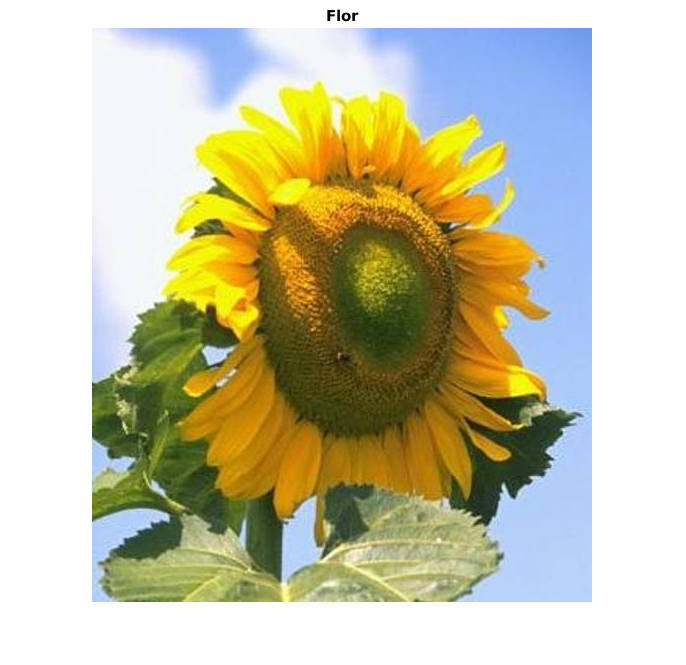

im = imread('Segmentades/Girasol/image_0724.jpg');
figure, imshow(im), title('Flor')

%FALTA FICAR LA IMATGE NORMALITZADA 

Proves


img = im2bw(im, graythresh(im));
img = ~img;
%EXTREURE FEATURES 
% https://www.mathworks.com/help/vision/ref/extractlbpfeatures.html
% https://www.mathworks.com/help/vision/ref/extracthogfeatures.html
% he vist que també podríem agafar la std2 i la mean2 de les imatges

% detectar corners i les més besties
corners   = detectFASTFeatures(rgb2gray(im));
strongest = selectStrongest(corners,3);
[hog2, validPoints,ptVis] = extractHOGFeatures(im,strongest)

hog2 = 3×36 single matrix
    0.1108    0.0386    0.0542    0.0232    0.1953    0.1979    0.0700    0.0665    0.0551    0.1997    0.1075    0.1631    0.0574    0.2728    0.2652    0.2728    0.2061    0.1165    0.0416    0.0345    0.0696    0.0677    0.2728    0.2728    0.0510    0.0307    0.0211    0.1551    0.1225    0.1980    0.0822    0.2728    0.2395    0.2654    0.2537    0.1410
    0.2525    0.1068    0.0107    0.0044    0.0398    0.0759    0.0878    0.1358    0.2490    0.3099    0.1503    0.0166    0.0127    0.0378    0.1316    0.1166    0.1350    0.2314    0.3099    0.3099    0.1103    0.0103    0.0417    0.1101    0.0949    0.1542    0.2649    0.3099    0.3099    0.0643    0.0350    0.0309    0.1524    0.1183    0.1147    0.1898
    0.1260    0.2122    0.2440    0.1160    0.1532    0.0965    0.0637    0.1293    0.1217    0.1975    0.2244    0.0818    0.0166    0.1078    0.2440    0.2440    0.1562    0.2049    0.1427    0.2440    0.2440    0.1745    0.2440    0.1284    0.0792  

validPoints =   3×1 cornerPoints array with properties:

    Location: [3×2 single]
      Metric: [3×1 single]
       Count: 3


ptVis = Visualization

   Type plot(ptVis) to visualize.

   Read-only properties:
                CellSize: [8 8]
               BlockSize: [2 2]
            BlockOverlap: [1 1]
                 NumBins: 9
    UseSignedOrientation: 0
              BinCenters: [18×1 double]


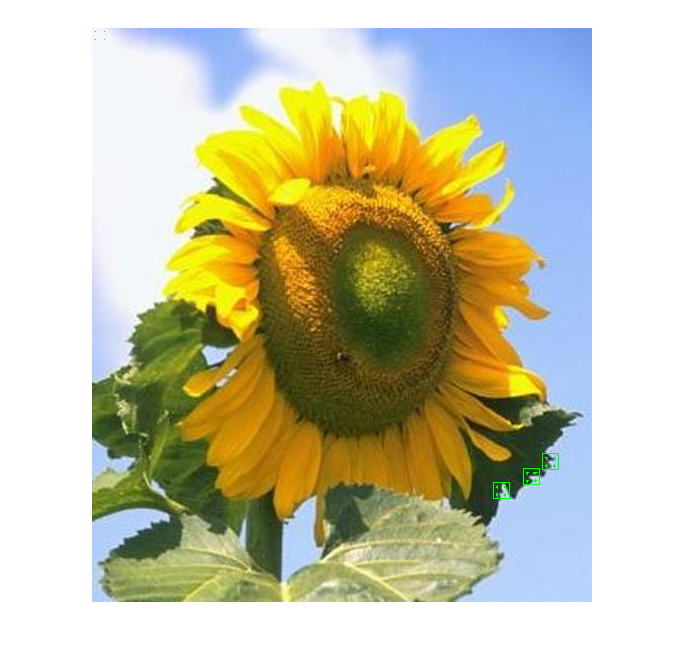

figure,imshow(im)
hold on
plot(ptVis,'Color','green');
hold off

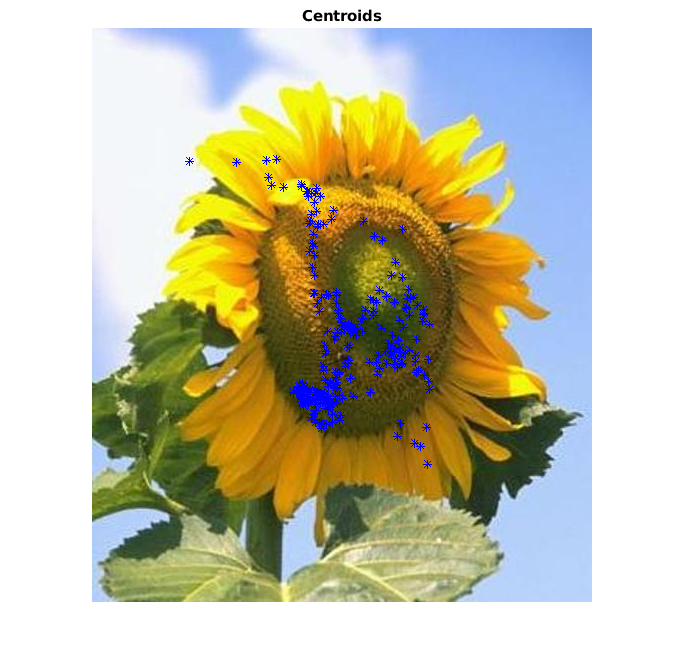



% information about local texture information
patternTextures = extractLBPFeatures(img);


[L, n] = bwlabel(img);
s = regionprops(im,'centroid');
%s = regionprops(L,'centroid','area','MajorAxisLength','MinorAxisLength','Orientation','BoundingBox');
figure, imshow(im), title('Centroids')
centroids = cat(1,s.Centroid);
hold on
plot(centroids(:,1),centroids(:,2),'b*')
hold off

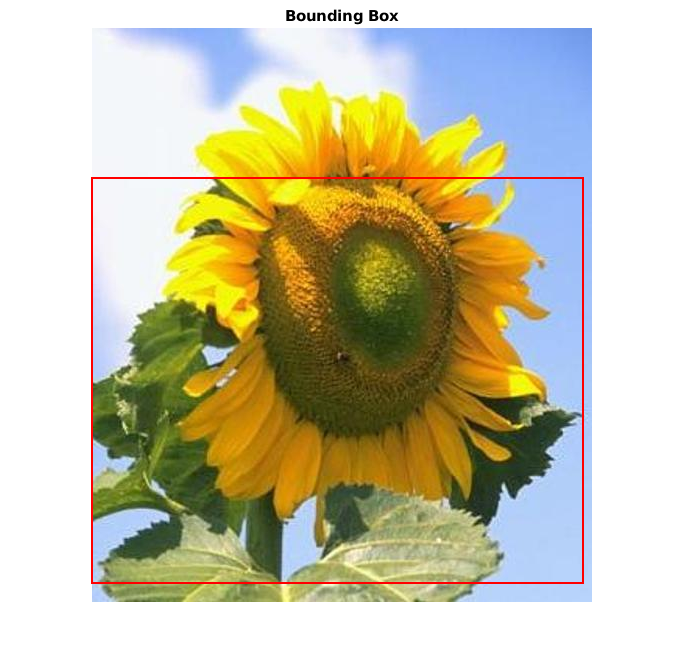



%NO FUNCIONA TT
st = regionprops(img, 'BoundingBox', 'Area' );
[maxArea, indexOfMax] = max([st.Area]);
imshow(im), title('Bounding Box')
hold on
rectangle('Position',[st(indexOfMax).BoundingBox(1),st(indexOfMax).BoundingBox(2),st(indexOfMax).BoundingBox(3),st(indexOfMax).BoundingBox(4)], 'EdgeColor','r','LineWidth',2 )
hold off

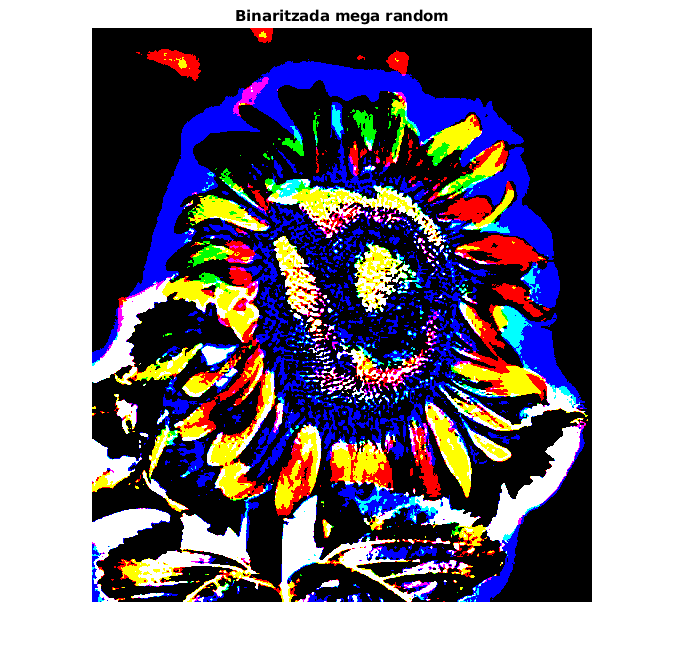


%BINARITZAR I LABLEJAR TO BE CONTINUED
binaritzada = imbinarize(im,'adaptive');
imshow(double(binaritzada)), title('Binaritzada mega random')

labeled = bwlabel(binaritzada,3)

Error using bwlabel
Expected input number 1, BW, to be two-dimensional.

Error in bwlabel (line 65)
validateattributes(BW, {'logical' 'numeric'}, {'real', '2d', 'nonsparse'}, ...

coloredLabels = label2rgb(labeled, 'hsv','k','shuffle')
subplot(3,3,5);
imshow(coloredLabels);
axis image;



### Detecció de vèrtexs (source: pràctica 11)

(Podria ser un feature la posició dels seus vèrtexs o la quantitat de vèrtexs)

k = 0.04;
h = ones(5);
[rows cols] = size(h);
h = h./(rows * cols);

sobel = [-1 0 1;
         -2 0 2;
         -1 0 1]
iX = imfilter(im,sobel,'conv')
iY = imfilter(im,sobel,'conv')
R = (imfilter(iX.^2,h,'conv').*imfilter(iY.^2,h,'conv')) - imfilter(iX.*iY,h,'conv').^2-k.*(imfilter(iX.^2,h,'conv')+imfilter(iY.^2,h,'conv')).^2;


ee = strel('cube',3);
dilatada = imdilate(R,ee);
R(dilatada>R) = 0;
RL = (R > 0);
hold on
figure,imshow(im), title('Vèrtexs de les flors')
[ys xs] = find(RL);
plot(xs,ys,'s','color','red')
hold off

### Color (source:pràctica 10)

Podem partir d'aquí, no obstant a la pràctica només miràvem els RB i no RGB

Npatches = 300
rb = NormalitzaRGB(im)
for j = 1:Npatches
    rb2 = patch_aleatori(rb,25,65);
    h = histo2D(rb2, 16)
    h = imgaussfilt3(h,1.5);
    S(j) = h
end
h1 = mean(j)
figure, surf(h1)